# Simulation Modes / Fast Restart

Copyright 2023-2024 The MathWorks, Inc.

## Overview

Simulation modes can have a great impact on simulation speed, especially if they are combined with Fast Restart.

There are three simulation modes available:

- **Normal**

- **Accelerator **

- **Rapid Accelerator**

If you click the RUN button or execute the sim command in Normal mode, the model is checked for updates, code generated (only for Accelerator Modes), initialized and then executed.

In case of Accelerator mode or Rapid-Accelerator Mode the model is additionally converted to c-code right after the check with the intention of a faster execution. The Accelerator Mode makes especially sense, if the runtime of a model is relatively long compared to the time needed for the code generation, which corresponds to the model size. 

If your model contains bigger sections of Stateflow or Simscape it might be that the acceleration effect is not that big compared to a pure Simulink model, because those sections are always already precompiled in c-code.

If s-functions are used within your model, you will need a tlc-file for the s-function to enable the Accelerator Mode or Rapid Accelerator Mode. 

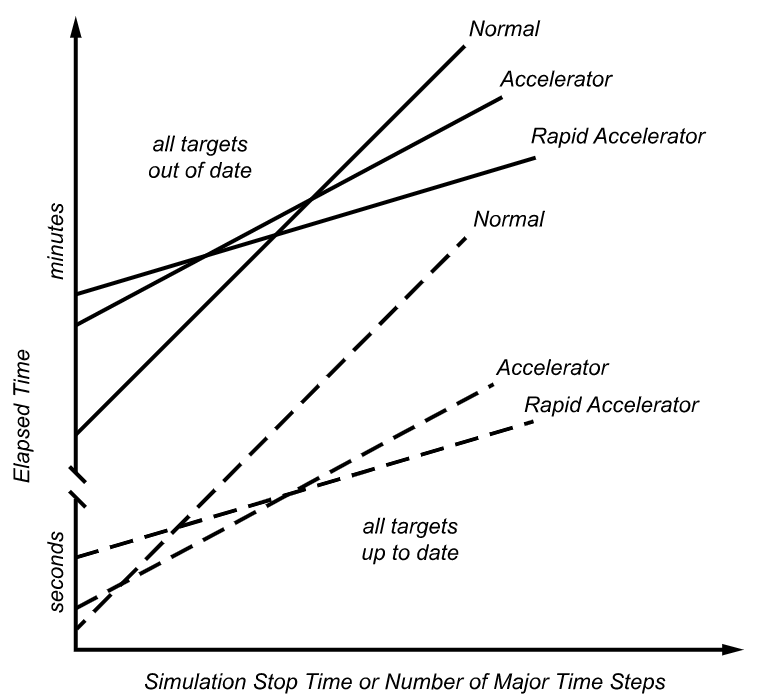              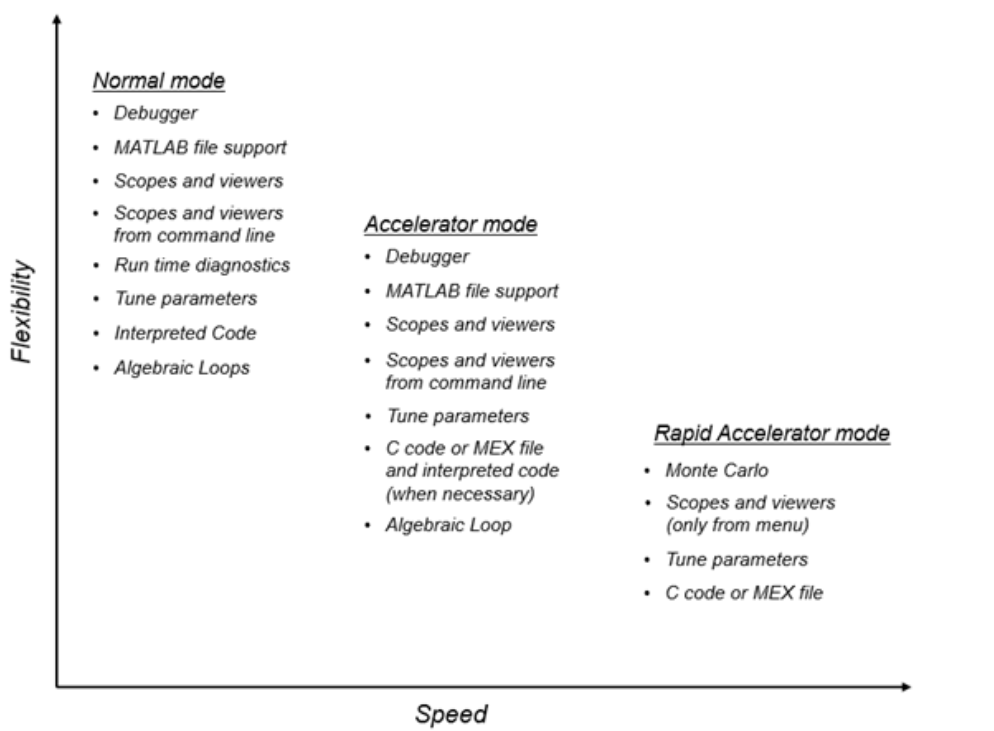

Additionally it will make sense to use the Fast Restart option (in Normal or Accelerator Mode) and to set up a model in such a way that a recompilation will not be needed even if parameters or model variants are changed. This can be done by using 

- tunable (versus inlined) parameters for all parameters that should be changed for an individual run (only for Rapid Accelerator Mode)

            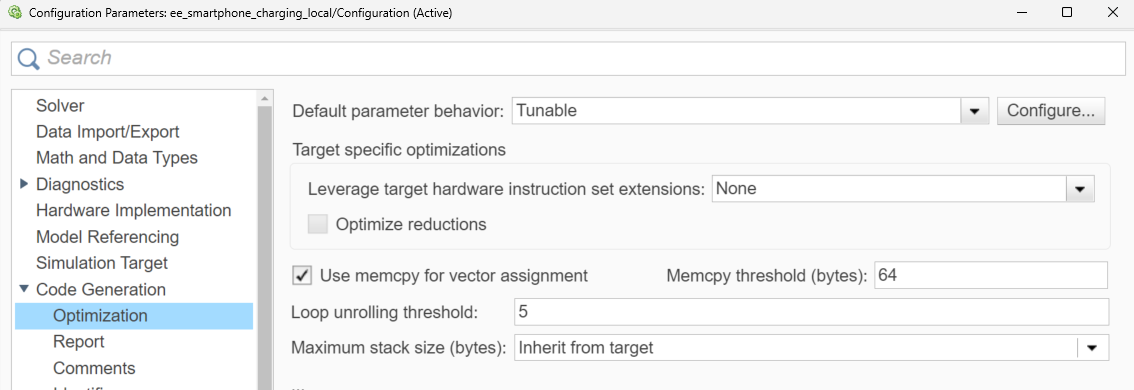

- run-time parameters for Simscape parametes that should be changed for an individual run (make sure only necessary parameters are set in that way, because the run-timr option itsself will cost a bit of simulation performance)

            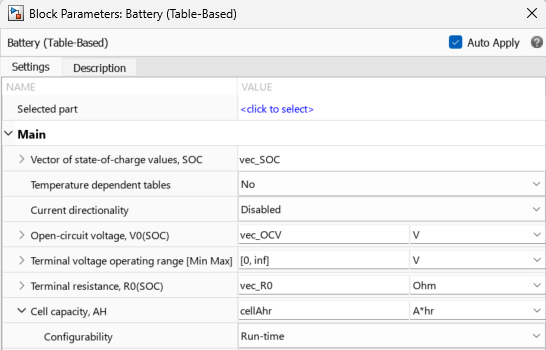

- startup activation variants for structural model options

            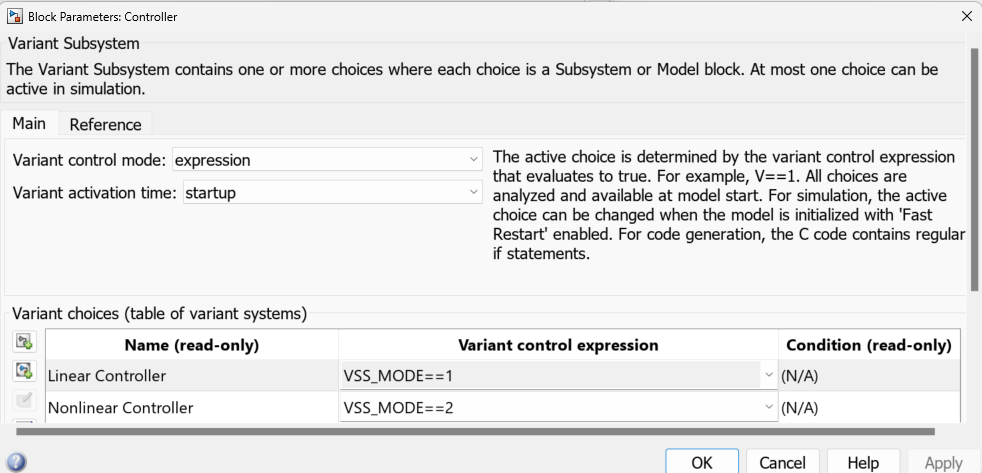

  

Fast Restart will prevent the check for model updates and will prevent recompilation as long as only parameters and no structures are changed in the model.

## Content

- Add time measurement to the model callback 

- Select simulation modes (Normal / Accelerator / Rapid Accelerator) 

- Especially models with a high percentage of Simulink blocks can be sped up with accelerator modes

- Simulink Profiler can be used to analyze the time spent for which model segments

All steps coded in this Live-Script can be applied also interactively in Simulink. They are coded for a better reproducability. 

### Step 1: Open the model

Three models are considered in more detail

1) SmartphoneBatteryCharging :                Simulink and Simscape components,             variable step solver

2) power_pwm :                                          Specialized Power Systems,                          variable step solver

3) slexVariantSubsystemsWithParSim_     Startup activation variants(Simulink only)       fixed step solver      

example = char("simscapeelectrical/SmartphoneBatteryChargingExample");

Path = pwd; 

if ~strcmp(example,'slexVariantSubsystemsWithParSim_')
    openExample(example);
    mdl = bdroot;
else
    mdl = example;
    open_system(mdl);
end

cd(Path);


Save model under new name

save_system(mdl,[Path,'/',mdl,'_local']);
mdl = [mdl,'_local'];

Set Callbacks for execution time measurement

if ~(contains(get_param(mdl,'StartFcn'),'tic'))
    set_param(mdl,'StartFcn',[get_param(mdl,'StartFcn'),char(13),'tic;']);
end
if ~(contains(get_param(mdl,'StopFcn'),'toc'))
    set_param(mdl,'StopFcn',[get_param(mdl,'StopFcn'),char(13),'toc']);
end

### Step 2: Choose the Simulation Mode

The Accelerator Modes typically allow faster simulation of the model.

Two different accelerator modes (JIT, classical), JIT is default, classical often better with Specialized Power Systems

Prerequisite is that all blocks can be c-code generated (s-functions need tlc-files)

set_param(mdl,'FastRestart','off');
simMode ="normal";
set_param(mdl,'SimulationMode',simMode);

### Step 3: Fast Restart / No Up-To-Date-Check 

- only for normal and accelerator mode

- Rapid Accelerator mode offers an option tp prevent up-to-date-check, if simulation run with sim command

Fast Restart will speed up second run of a model by skipping the model initialization. 

Parameters can be changed if defined as tunable parameters (Simulink ) or runtime parameters (Simscape)

ReinitMode = "No FastRestart || UpToDateCheck";     % Startup Variants need 'RapidAcceleratorUpToDateCheck' set to 'on'
if ~strcmp(simMode,'rapid-accelerator')
    % normal and accelerator mode
    if strcmp(ReinitMode,'FastRestart || No UpToDateCheck')
        set_param(mdl,'FastRestart','on');
    else
        set_param(mdl,'FastRestart','off');
    end
end

### Step 4: Run the Simulation

Run the Simulation by pressing the RUN or with the sim command

if ~strcmp(simMode,'rapid-accelerator')
    % normal and accelerator mode
     sim(mdl);
else
    % rapid accelerator mode
    if strcmp(ReinitMode,'FastRestart || No UpToDateCheck')
        sim(mdl,'RapidAcceleratorUpToDateCheck','off'); % only if execution target existing
    else
        sim(mdl,'RapidAcceleratorUpToDateCheck','on'); 
    end
end

Elapsed time is 15.119016 seconds.


Show the elapsed time (2nd run with Fast Restart  ||  No Up-To-Date-Check)

Model    / Mode                                       **Normal               Accelerator            Rapid Accelerator  **    

**SmartphoneBatteryCharging    **             30sec                    15sec                            32sec

**ThreePhaseASM                                      **12sec                    2,5sec                           2,5sec

**slexVariantSubsystemsWithParSim_**    22sec                   12sec                            7.6 sec